% AUDIO EN MATLAB
%----------------

% --> Paso 1: Escaneo del dispositivo
%------------------------------------
audioInfo = audiodevinfo

audioInfo = struct with fields:
     input: [1×2 struct]
    output: [1×2 struct]



% El resultado se puede ver en el Worksapce de variables.

% --> Paso 2: Crear objeto de audio.
%-----------------------------------

Id = 1;
 % Frecuencia de muestreo, se recomienda más del doble de la máxima
 % frecuencia desada.
fs       = 8000 ;
CH_No    = 1  ;
BitDepth = 8  ; % Bits del audio.

% Deault: fs=8kHz, BitDepth=8 bit, 1 Ch.
recordObject = audiorecorder(fs,BitDepth,CH_No,Id)

recordObject =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: 1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


% Paso 3: Grabación.
% ------------------

T = 5; % Tiempo de grabación en (segundos)
recordblocking(recordObject,T);

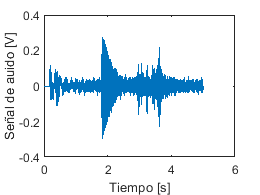

% Paso 4: Ploteo
%---------------

% Que wen rolon de Lo-fi u w u
data_grabacion = getaudiodata(recordObject);

t = 1/fs:1/fs:T;
plot(t,data_grabacion)
xlabel("Tiempo [s]")
ylabel("Señal de auido [V]")

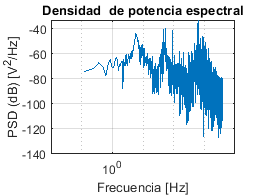

% VARIABLES PARA EL PERIODOGRAMA Y ESPECTROGRAMA
% ---------------------------------------------

% Parámetros importantes
N = numel(data_grabacion); % Número de muestras de la señal
N_spect = N/50 ; % Número de muestras de la señal.

% función de descomposición
[Pxx_Per, F_Pxx] = periodogram(data_grabacion,rectwin(N),[],fs);
[a,F_Spect,T_Spect,Pxx_Spect] = spectrogram(data_grabacion,rectwin(N_spect),[],[],fs);

% Buscamos la oscilación más fuerte en un espectrograma: Time*frequency
% ridge
fr = tfridge(Pxx_Spect,F_Spect);



% PERIODOGRAMA

figure
semilogx(F_Pxx,10*log10(Pxx_Per))
title("Densidad  de potencia espectral")
xlabel("Frecuencia [Hz]")
ylabel("PSD (dB) [V^2/Hz]")
grid on

% ESPECTROGAMA
figure
p = pcolor(T_Spect,F_Spect,10*log10(Pxx_Spect))

p =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 0.3500 0.4000 0.4500 0.5000 0.5500 0.6000 0.6500 0.7000 0.7500 0.8000 0.8500 0.9000 0.9500 1 1.0500 1.1000 1.1500 1.2000 1.2500 1.3000 1.3500 1.4000 1.4500 1.5000 1.5500 1.6000 1.6500 … ]
           YData: [513×1 double]
           ZData: [513×99 double]
           CData: [513×99 double]

  Show all properties


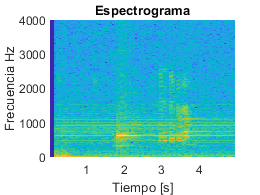

set(p,"EdgeColor","none")
xlabel("Tiempo [s]")
ylabel("Frecuencia Hz")
title("Espectrograma")

% Grabar Audio
%-------------
audiowrite("lo-fi_grabación.wav",data_grabacion,fs)